# Thermo 2019 chapter 4 

Detailed corrections

## **Exo 4.1** Water reservoir

A water reservoir (system) is maintained at $T_1=97\,\mathrm{°C}$. The surroundings air is a temperature reservoir at $T_2=20\,\mathrm{°C}$. After some time, $Q = - 4180\,\mathrm J$ have been transferred to the surrounding air through the reservoir wall. Consider the surrounding a thermal reservoir, and noting that for this exercise since the work is nill, $\Delta U=Q$ so that heat does not depend on the path ($Q_{irr}=Q_{rev}$) , calculate :

**a) ** The entropy variation of the sytem (water). Can you conclude on the reversibility of the process?

    
$$dS_\sigma=\frac{\delta Q_{rev}}{T_1}$$
 
$$\rightarrow \Delta S_\sigma=\frac{Q_{rev}}{T_1}\iff\Delta S_\sigma=\frac{Q}{T_1}$$


    It does not give any indication on the reversibility of the process.

T1=273+97; T2=273+20; Q=-4180;
DS_s=Q/T1; fprintf('DS_s = %1.1f J/K',DS_s)

DS_s = -11.3 J/K

**b)** The exchanged entropy between the system and  the surrounding air. Can you conclude on the reversibility of the process?

    
$$S_e=\frac{Q}{T_2}$$


 It also does not give any indication on the reversibility of the process.

S_e=Q/T2; ; fprintf('S_e = %1.1f J/K',S_e)

S_e = -14.3 J/K

**c)** The created entropy between the system and  the surrounding air. Can you conclude on the reversibility of the process?

    
$$S_c=\Delta S_\sigma-S_e$$


S_c=DS_s-S_e; ; fprintf('S_c = %1.1f J/K',S_c)

S_c = 3.0 J/K

the created entropy  $S_c >0$ so that the process is irreversible. 

**d)** What if $Q = 4180\,\mathrm J$

    All the values are of opposite signs then $S_c=-2.97\,\mathrm{JK^{-1}}$ negative so that the process is not possible.

## **Exo 4.2 Water to thermal reservoir**

Calculate the entropy variation of liquid water for the following processes and conclude on the reversibility of the process:

**a)** 1 kg of liquid water at 20°C is related to a thermal reservoir at 370 K.

   The mass of water is $m=1\,\mathrm{kg}$ and the specific thermal heat coefficient of liquid water is $c_l=4.18\times 10^3\,\mathrm{kJ\cdot kg^{-1}}$ The initial temperature is $T_i=293\,\mathrm{K}$ and the final temperature is $T_3=370\;\mathrm{K}$. The entropy variation of the system is  :    

    
$$\Delta S_{\sigma }^a =\int_{T_i }^{T_3 } \frac{mc_l }{T}dT$$
 
$$\iff \Delta S_\sigma^a=mc_l\ln \frac{T_3}{T_i}$$
  

    The exchange entropy with the thermal reservoire which is at constant temperature $T_{res}=T_3$  is :

     
$$S_e^a=\frac{Q}{T_{res}}=\frac{mc_l(T_3-T_i)}{T_3}$$


    Therefore the created entropy is équal to $S_i^a=\Delta S_\sigma^a-S_e^a$

%example using the Symbolic Math Toolbox to make the integration
clear all
syms Ti T3 T m Cl
assume(Ti > 0)
assume(T3 > 0)
assume(T > 0)
DS_s_a=int(m*Cl/T,T,Ti,T3)

$$DS\_s\_a = \mathrm{Cl}\,m\,\left(\log\left(T_{3}\right)-\log\left(\mathrm{Ti}\right)\right)$$

S_e_a=m*Cl*(T3-Ti)/T3;
Cl=4.18; m=1000; Ti =20+273; T3=370; % data for numérical calculation
DS_s_a=eval(DS_s_a); fprintf('DS_s_a = %1.0f J/K',DS_s_a) % in J/K

DS_s_a = 975 J/K

S_e_a=eval(S_e_a); fprintf('S_e_a = %1.0f J/K',S_e_a) % in J/K

S_e_a = 870 J/K

Sc_a=DS_s_a-S_e_a; fprintf('Sc_a = %1.0f J/K',Sc_a) % in J/K

Sc_a = 105 J/K

the created entropy is positive, indicating an irreversible process

**b) ** 1 kg of liquid water at 20°C is successively related to a thermal reservoir at 320 K and to another one at 370 K.

We consider the pressure constant and that there is no vaporisation of the water. The temperature of the first thermal reservoir is $T_2=320\,\mathrm{K}$. The calculation of the entropy variation of the system is the same as that calculated in question (a), since the entropy is a state function :

   
$$\Delta S_{\sigma }^b =\Delta S_{\sigma }^a =\int_{T_i }^{T_3 } \frac{mc_l }{T}dT$$
   

The exchange entropy is not the same, since the system is related to two reservoirs at two different temperatures. This must be decomposed into two terms :

     
$$S_e^b=\frac{mc_l(T_2-T_i)}{T_2}+\frac{mc_l(T_3-T_2)}{T_3}$$


    
$$S_c^b=\Delta S_\sigma^b - S_e^b$$


clear all
syms Ti T2 T3 T m Cl
assume(Ti > 0)
assume(T3 > 0)
assume(T > 0)
DS_s=int(m*Cl/T,T,Ti,T3)

$$DS\_s = \mathrm{Cl}\,m\,\left(\log\left(T_{3}\right)-\log\left(\mathrm{Ti}\right)\right)$$

S_e=m*Cl*(T2-Ti)/T2+m*Cl*(T3-T2)/T3;
Cl=4.18; m=1000; Ti =20+273;  T2=320; T3=370;
DS_s_b=eval(DS_s); fprintf('DS_s_b = %1.0f J/K',DS_s_b)

DS_s_b = 975 J/K

S_e_b=eval(S_e); fprintf('S_e_b = %1.0f J/K',S_e_b)

S_e_b = 918 J/K

S_c_b=DS_s_b-S_e_b; fprintf('S_c_b = %1.0f J/K',S_c_b)

S_c_b = 58 J/K

So the created entropy varies from +105 J/K to + 58 J/K, since in the second case, we have an intermediary point decreasing the temperature mismatch between the system and the surroundings. 

## Exo 4-3 Supercooled water

In the initial state A, we consider one mole of liquid water at -10°C (supercooled water) defining a system $\sigma$. In the final state B, the system is related to a temperature reservoir $\sigma_1 \;$at temperature $\theta$ and we suppose that water has crystallised. Calculate the entropy variations of the system ${\Delta S}_{\sigma }$,  for the three cases : (a) $\theta =-10\textrm{°C}$,  (b) $\theta =0\textrm{°C}\;$and (c) $\theta =+10\textrm{°C}$. For this purpose consider a reversible process  transforming the liquid water to solid water. 

Since the quantity is given in mole $n=1\,\mathrm{mol}$, we consider the molar thermal heat coefficient of water, both as solid and liquid : $\bar C_l$ and $\bar C_s$ . However, these values are calculated from the specific values, according to : $\bar C_l=M_wc_l$ and $\bar C_s=M_wc_s$. The considered temperatures are $T_i=263\,\mathrm{K}$, $T_m=273\,\mathrm{K}$ and $T_{10}=283\,\mathrm{K}$ where $T_m$ is the melting temperature of ice, i.e. the equilibrium temperature between solid and liquid water under $1\,\mathrm{bar}$.

**(a)** One needs to consider a reversible path as : liquid ($T_i$) --> liquid ($T_m$) --> solid ($T_m$) -->solid ($T_i$)

   
$$\Delta S_\sigma^a=\int_{T_i}^{T_m}\frac{\bar C_l}{T}dT-\frac{\Delta_{fus}\bar H}{T_m}+\int_{T_m}^{T_i}\frac{\bar C_s}{T}dT\iff \Delta S_\sigma^a=\bar C_l\ln\frac{T_m}{T_i}-\frac{\Delta_{fus}\bar H}{T_m}+\bar C_s\ln\frac{T_i}{T_m}$$


   the heat exchanged is : $Q^a=\bar C_l(T_m-T_i)-\Delta_{fus}\bar H+\bar C_s(T_i-T_m)$ 

   During that step, the temperature of the surroundings is $T_i$, therfore the exchange entropy is :

    
$$S_e^a=\frac{Q^a}{T_i}\iff S_e^a=\frac{\bar C_l(T_m-T_i)-\Delta_{fus}\bar H+\bar C_s(T_i-T_m)}{T_i}$$


**(b)** This time the reversible path is : liquid ($T_i$) --> liquid ($T_m$) --> solid ($T_m$) 


$$\Delta S_\sigma^b=\int_{T_i}^{T_m}\frac{\bar C_l}{T}dT-\frac{\Delta_{fus}\bar H}{T_m} \iff \Delta S_\sigma^b=\bar C_l\ln\frac{T_m}{T_i}-\frac{\Delta_{fus}\bar H}{T_m}$$


The heat exchanged is : $Q^b=\bar C_l(T_m-T_i)-\Delta_{fus}\bar H$, and since the surroudings temperature is $T_m$


$$S_e^b=\frac{Q^b}{T_m}\iff S_e^b=\frac{\bar C_l(T_m-T_i)-\Delta_{fus}\bar H_m}{T_m}$$


**(c)** The reversible path is : liquid ($T_i$) --> liquid ($T_m$) --> solid ($T_m$) -->solid ($T_{10}$)

   
$$\Delta S_\sigma^c=\int_{T_i}^{T_m}\frac{\bar C_l}{T}dT-\frac{\Delta_{fus}\bar H}{T_m}+\int_{T_m}^{T_{10}}\frac{\bar C_s}{T}dT\iff \Delta S_\sigma^c=\bar C_l\ln\frac{T_m}{T_i}-\frac{\Delta_{fus}\bar H}{T_m}+\bar C_s\ln\frac{T_{10}}{T_m}$$


the heat exchanged is $Q^c=\bar C_l(T_m-T_i)-\Delta_{fus}\bar H+\bar C_s(T_{10}-T_m)$  and the surroundings temperature being $T_{10}$, the exchange entropy is :

    
$$S_e^c=\frac{Q^c}{T_{10}}=\frac{\bar C_l(T_m-T_i)-\Delta_{fus}\bar H+\bar C_s(T_{10}-T_m)}{T_{10}}$$


In order to use the possibilities of Matlab calculation, we make a literal calculation considering the final temperature $T_f$ successfully equals to $T_i$, $T_m$ and $T_{10}$:

clear all
% literal calculation
syms Ti Tm T10 T M_w Cs Cl DfH Tf
assume(Ti > 0)
assume(Tm > 0)
assume(T > 0)
DS_s=int(M_w*Cl/T,T,Ti,Tm)-M_w*DfH/Tm+int(M_w*Cs/T,T,Tm,Tf);
S_e=(M_w*Cl*(Tm-Ti)-M_w*DfH+M_w*Cs*(Tf-Tm))/Tf;

%numerical calculation
Ti=263; Tm=273; M_w=18e-3; Cl=4.18e3;Cs=2.09e3;DfH=334.4e3;
% ------- first case (a)----------
Tf=263; % in K
DS_s_a=eval(DS_s);
S_e_a=eval(S_e);
S_c_a=DS_s_a-S_e_a; % in J/K
% --------second case (b)----------
Tf=273;
DS_s_b=eval(DS_s);
S_e_b=eval(S_e);
S_c_b=DS_s_b-S_e_b; % in J/K
% -------- third case (c) ----------
Tf=283;
DS_s_c=eval(DS_s);
S_e_c=eval(S_e);
S_c_c=DS_s_c-S_e_c; % in J/K

% ---------put values in table for the display-------
Tf=['263K';'273K';'283K'];
DS_s=[DS_s_a;DS_s_b;DS_s_c];
S_e=[S_e_a;S_e_b;S_e_c];
S_c=[S_c_a;S_c_b;S_c_c];
tab=table(Tf,DS_s,S_e,S_c)

tab = 3×4 table
     Tf      DS_s        S_e        S_c   
    ____    _______    _______    ________
    263K    -20.644    -21.456     0.81182
    273K    -19.241    -19.292    0.051745
    283K    -17.887    -17.281    -0.60591

Considering the different values 

$S_c^a>0$ therefore the process is indeed irreversible, like $S_c^b$, which however creates less entropy, so it is closer to a reversible process than (a).

$S_c^c<0$ which shows that this process is impossible.

## Exo 4.4 Several Paths from the same point

From state A $\mathrm{(1\,atm, 30\,L, 250\,K)}$ an ideal gas undergoes following processes:

- AB-a : Isothermal reversible until $P_B =1.5\,\mathrm{atm}$

- AB-b : Monothermal irreversible with $P_{ext}=1.5\,\mathrm{atm}$ during the process

- AC-a : Isochoric reversible until $T_C=300\,\mathrm{K}$

- AC-b : Isochoric irreversible with $T_{ext}=300\,\mathrm{K}$ during the process

- AD-a : Isobaric reversible until $T_D=300\,\mathrm{K}$

- AD-b : Monobaric irreversible with $T_{ext}=300\,\mathrm{K}$ during the process

- AE : Adiabatic reversible until $P_E=1.5\,\mathrm{atm}$

- AE’: Adiabatic irreversible with $P_{ext}=1.5\,\mathrm{atm}$ during the process

Find the values of the state variables $(P,V,T)$ for the equilibrium states B, C, D, E, E’

Fill a table giving for all processes the values of $W, Q, \Delta U, \Delta H, \Delta S, S_e, S_c$

Make 2 graphs, one $(P,V )$ one $(T,S)$ representing these processes.

### States variables P,V and T in the different states :

Let's set $P_A=1\,\mathrm{atm}$, $V_A=30\,\mathrm{L}$ and $T_A=250\,\mathrm{K}$.

**AB-a **:  reversible isothermal : $T=Cte$ then $V_B=V_A\frac{P_A}{P_B}$

**AC-a** : reversible isochoric : $V=Cte$ then $\frac{T_A}{P_A}=\frac{T_C}{P_C}$ $\iff P_C=P_A\frac{T_C}{T_A}$

**AD-a** : reversible isobaric : $P=Cte$ then $\frac{T_A}{V_A}=\frac{T_D}{V_D}$ $\iff V_D=V_A\frac{T_D}{T_A}$

**AE **: reversible adiabatic : $Q=0$ and reversible $P_A{V_A}^\gamma=P_E{V_E}^\gamma$ $\iff V_E=V_A\Big(\frac{P_A}{P_E}\Big)^\frac{1}{\gamma}$

**AE'** : irreversible adiabatic :  $Q=0\iff \Delta U=W$  (irreversible, one can only calculate variation between E' and A.

             
$$\iff n\bar C_v(T_{E'}-T_A)=-P_{ext}(V_{E'}-V_A)$$
        
$$P_{E\prime}=P_{ext}$$
  
$$P_{E\prime}V_{E\prime}=nRT_{E\prime}$$


            
$$\iff n\bar C_v(T_{E'}-T_A)=-nRT_{E'}+P_{ext}V_A$$


            
$$\iff T_{E'}=\frac{n\bar C_vT_A+P_{ext}V_A}{n(\bar C_v+R)}$$


R=8.314; Cv=20.8; Cp=R+Cv; g=Cp/Cv; 
PA=101325; VA=30e-3; TA=250;
n=PA*VA/(R*TA);
PB=1.5*101325; VB=VA*PA/PB; TB=PB*VB/n/R;
TC=300; PC=PA*TC/TA; VC=n*R*TC/PC;
TD=300; VD=VA*TD/TA; PD=n*R*TD/VD;
PE=1.5*101325; VE=VA*(PA/PE)^(1/g); TE=PE*VE/n/R;
TEp=(n*Cv*TA+PE*VA)/(n*(Cv+R)); VEp=n*R*TEp/PE;
% put the state values in a table
etat=['A ';'B ';'C ';'D ';'E ';'Ep'];
P=[PA;PB;PC;PD;PE;PE]/101325; % in atm
V=[VA;VB;VC;VD;VE;VEp]*1000; % in L
T=[TA;TB;TC;TD;TE;TEp]; % in K
tab=table(etat,P,V,T)

tab = 6×4 table
    etat     P       V         T   
    ____    ___    ______    ______
     A        1        30       250
     B      1.5        20       250
     C      1.2        30       300
     D        1        36       300
     E      1.5    22.455    280.69
     Ep     1.5    22.856     285.7

### Energy and entropy variations of the different processes

State variables are path independant so that the variations $\Delta H$, $\Delta U$ and $\Delta S_\sigma$ between two points are identical, i.e. identical for reversible and irreversible paths. 

    $\left\{\begin{array}{cc} \Delta U_{AXa}=\Delta U_{AXb}=\Delta U_{AX}\\ \Delta H_{AXa}=\Delta H_{AXb}=\Delta H_{AX} \\ \Delta S_{AXa}=\Delta S_{AXb}=\Delta S_{AX} \end{array}$      where $X$ represents $A, B, C$or $D$.

For reversibles path : $S_{c,AXa}=0$ and $S_{c,AE}=0
$ therefore  $S_{e,AXa}=\Delta S_{AXa}$ and $S_{e,AE}=\Delta S_{AE}$

**ABa : ** $\Delta U_{AB}=0$ ($T=Cte$ for an ideal gas), $W_{ABa}=-Q_{ABa}$ and $W_{ABa}=-nRT_A\ln\frac{V_B}{V_A}$ 

$H=U+PV$$\iff\Delta H_{AB}=\Delta U_{AB}+\Delta (PV)=0$  (isothermal process, $PV=Cte$)

$dS_{AB}=\frac{\delta Q_{AB}}{T_A}$$\iff\Delta S_{AB}=\frac{Q_{ABa}}{T_A}=nR\ln\frac{V_B}{V_A}$   reversible : $S_c=0$ and $S_e=\Delta S_{AB}$

**ABb** :  $\delta W_{ABb}=-P_{ext}dV$        $P_{ext}=Cte=P_B$   $\iff W_{ABb}=-P_B(V_B-V_A)$, 

$Q_{ABb}=-W_{ABb}$, state variables identicals 


$$S_{e,ABb}=\frac{Q_{ABb}}{T_B}=\frac{-W_{ABb}}{T_B}=\frac{P_B(V_B-V_A)}{T_B}$$
  
$$S_{c,ABb}=\Delta S_{AB}-S_{e,ABb}$$


**ACa** : isochoric $\Delta V=0$$\iff W_{ACa}=0$; $Q_{ACa}=\Delta U_{AC}=n\bar C_v(T_C-T_A)$ ;  

$H=U+PV$$\iff \Delta H_{AC}=\Delta U_{AC}+\Delta(PV)$ $\iff \Delta H_{AC}=\Delta U_{AC}+V_A(P_C-P_A)$ since $V_A=V_C$

 $dS_{AC}=\frac{\delta Q_{AC}}{T}\iff dS_{AC}=\frac{n\bar C_vdT}{T}$ $\iff\Delta S_{AC}=n\bar C_v\ln\frac{T_C}{T_A}$ ;     $S_{e,ACa}=\Delta S_{ACa}$ ; $S_{c,ACa}=0$

**ACb** :  still isochoric : $W_{ACb}=0$ $\iff Q_{ACb}=\Delta U_{ACb}=\Delta U_{AC}$

$S_{e,ACb}=\frac{Q_{ACb}}{T_C}\iff S_{e,ACb}=\frac{\Delta U_{AC}}{T_C}$ ; $S_{c,ACb}=\Delta S_{ACa}-S_{e,ACb}$

**ADa **:  Isobaric : $W_{ADa}=-P_D(V_D-V_A)$ ; $Q_{ADa}=\Delta H_{AD}=n\bar C_p(T_D-T_A)$ ; $\Delta U_{AD}=W_{ADa}+Q_{ADa}$ ; 


$$dS_{AD}=\frac{\delta Q_{AD}}{T}\iff dS_{AD}=\frac{n\bar C_pdT}{T}$$

$$\iff\Delta S_{AD}=n\bar C_p\ln\frac{T_D}{T_A}$$


**ADb** : $W_{ADb}=-P_{ext}(V_D-V_C)\iff W_{ADb}=-P_{D}(V_D-V_C)=W_{ADa}$   since $Q_{ADb}=\Delta U_{AD}-W_{ADb}$ then $Q_{ADb}=Q_{ADa}$

$S_{e,ADb}=\frac{Q_{ADb}}{T_D}=\frac{Q_{ADa}}{T_D}$ ; $S_{c,ADb}=\Delta S_{AD}-S_{e,ADb}$

**AE **: adiabatic $Q_{AE}=0$, $W_{AE}=\Delta U_{AE}=n\bar C_v(T_E-T_A)$;  

$\Delta H_{AE}=\Delta U_{AE}+P_EV_E-P_AV_A$$\iff \Delta H_{AE}=\Delta U_{AE}+nR(T_E-T_A)$; $\Delta S_{AE}=0$

**AE'** : $Q_{AE'}=0, W_{AE'}=\Delta U_{AE'}=n\bar C_v(T_{E'}-T_A)$ ; 

$\Delta H_{AE\prime}=\Delta U_{AE\prime}+P_{E\prime}V_{E\prime}-P_AV_A$$\iff\Delta H_{AE'}=\Delta U_{AE'}+nR(T_E'-T_A)$; 

$\Delta S_{AE'}=\Delta S_{AE}+\Delta S_{EE'}$   with $\Delta S_{AE}=0$  and for $EE\prime$ one consider any reversible path, for instance isobaric, so that $dS_{EE\prime}=\frac{n\bar C_pdT}{T}\iff \Delta S_{EE\prime}=n\bar C_p\ln\frac{T_{E\prime}}{T_E}$ then $\Delta S_{AE\prime}=n\bar C_p\ln\frac{T_{E\prime}}{T_E}$ ;

$S_{e,AE'}=0$  since $Q_{AE'}=0$;  then $S_{c,AE'}=\Delta S_{AE'}-S_{e,AE'}$  $\iff S_{c,AE'}=\Delta S_{AE'}$

### Numerical calculations of the different variables :

%--AB--
W_ABa=-n*R*TA*log(VB/VA); % in J
DS_AB=n*R*log(VB/VA);  % in JK-1
W_ABb=-PB*(VB-VA);
Se_ABb=PB*(VB-VA)/TB;
Sc_ABb=DS_AB-Se_ABb;
%--AC--
Q_ACa=n*Cv*(TC-TA);
DU_AC=Q_ACa;
DH_AC=DU_AC+VA*(PC-PA);
DS_AC=n*Cv*log(TC/TA);
Se_ACb=Q_ACa/TC;
Sc_ACb=DS_AC-Se_ACb;
%--AD--
W_ADa=-PD*(VD-VA);
Q_ADa=n*Cp*(TD-TA);
DH_AD=Q_ADa;
DU_AD=W_ADa+Q_ADa;
DS_AD=n*Cp*log(TD/TA);
Se_ADb=Q_ADa/TD;
Sc_ADb=DS_AD-Se_ADb;
%--AE--
Q_AE=0;
W_AE=n*Cv*(TE-TA);
DU_AE=W_AE;
DH_AE=DU_AE+n*R*(TE-TA);
DS_AE=0;
%--AE'--
Q_AEp=0;
W_AEp=n*Cv*(TEp-TA);
DU_AEp=W_AEp;
DH_AEp=DU_AEp+n*R*(TEp-TA);
DS_AEp=n*Cp*log(TEp/TE);
Se_AEp=0;
Sc_AEp=DS_AEp;
%--- put the values in a table---------
trans=['ABa';'ABb';'ACa';'ACb';'ADa';'ADb';'AE ';'AEp'];
W=[W_ABa;W_ABb;0;0;W_ADa;W_ADa;W_AE;W_AEp];
Q=[-W_ABa;-W_ABb;Q_ACa;Q_ACa;Q_ADa;Q_ADa;Q_AE;Q_AEp];
DU=W+Q;
DH=[0;0;DH_AC;DH_AC;DH_AD;DH_AD;DH_AE;DH_AEp];
DS=[DS_AB;DS_AB;DS_AC;DS_AC;DS_AD;DS_AD;DS_AE;DS_AEp];
Sc=[0;Sc_ABb;0;Sc_ACb;0;Sc_ADb;0;Sc_AEp];
tab=table(trans,W,Q,DU,DH,DS,Sc)

tab = 8×7 table
    trans       W          Q         DU        DH        DS         Sc   
    _____    _______    _______    ______    ______    _______    _______
     ABa      1232.5    -1232.5         0         0    -4.9301          0
     ABb      1519.9    -1519.9         0         0    -4.9301     1.1494
     ACa           0       1521      1521    2128.9     5.5461          0
     ACb           0       1521      1521    2128.9     5.5461    0.47621
     ADa     -607.95     2128.9      1521    2128.9      7.763          0
     ADb     -607.95     2128.9      1521    2128.9      7.763    0.66656
     AE       933.55          0    933.55    1306.7          0          0
     AEp      1085.8          0    1085.8    1519.9    0.75277    0.75277

### Plot the different reversible curves on a P(V) diagram

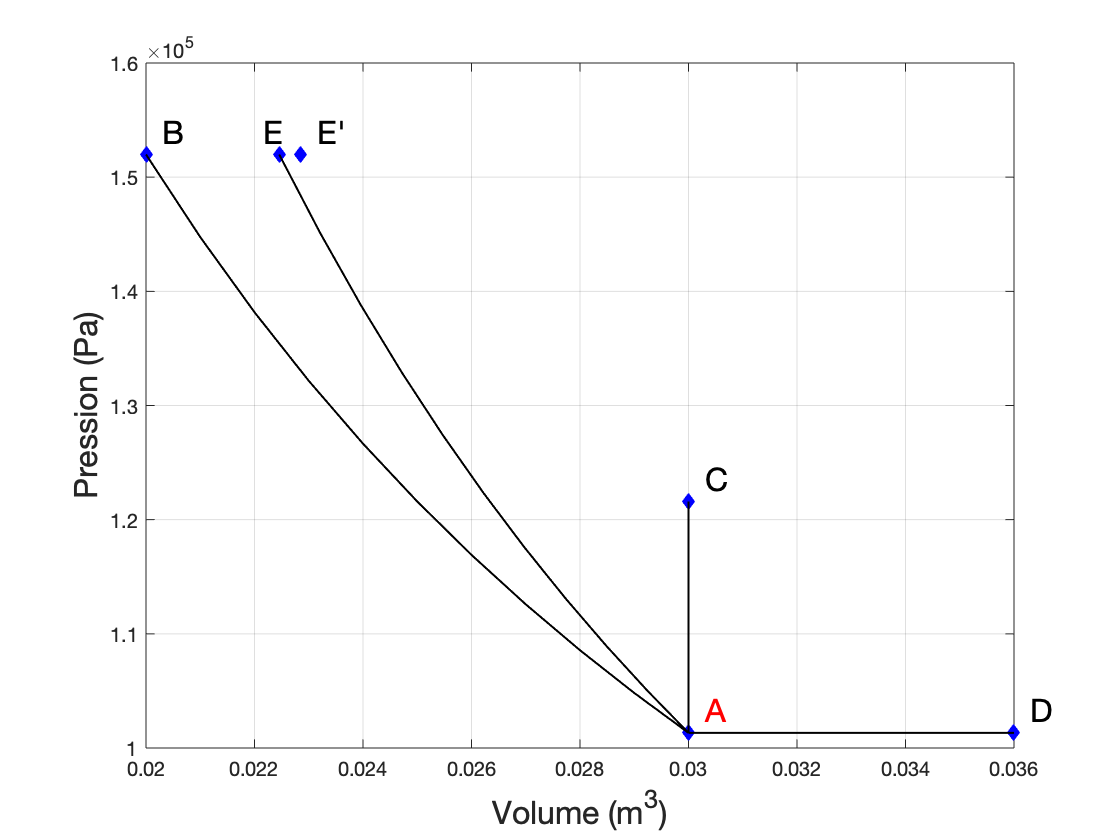

% plot of the different curves
plot(V/1000,P*101325,'db','MarkerFaceColor','b') % car V,P était en L et atm
xv=0.0003; xp=2e3; % decalage écriture
text(VA+xv,PA+xp,'A','FontSize',16,'color','r')
text(VB+xv,PB+xp,'B','FontSize',16,'color','k')
text(VC+xv,PC+xp,'C','FontSize',16,'color','k')
text(VD+xv,PD+xp,'D','FontSize',16,'color','k')
text(VE-xv,PE+xp,'E','FontSize',16,'color','k')
text(VEp+xv,PE+xp,'E''','FontSize',16,'color','k')
xlabel('Volume (m^3)','FontSize',16)
ylabel('Pression (Pa)','FontSize',16)
grid on
hold on
Vx=VA:(VB-VA)/10:VB;
Px=VA*PA./Vx;
plot(Vx,Px,'-k','linewidth',1)  % isotherme
Vx=[VA VC]; Px=[PA PC];
plot(Vx,Px,'-k','linewidth',1)   % ischore
Vx=[VA VD]; Px=[PA PD];
plot(Vx,Px,'-k','linewidth',1)   % isbar
Vx=VA:(VE-VA)/10:VE;
Px=PA*(VA./Vx).^g;
plot(Vx,Px,'-k','linewidth',1)  % isotherme
hold off

### Plot the different reversible curves on a T(S) diagram

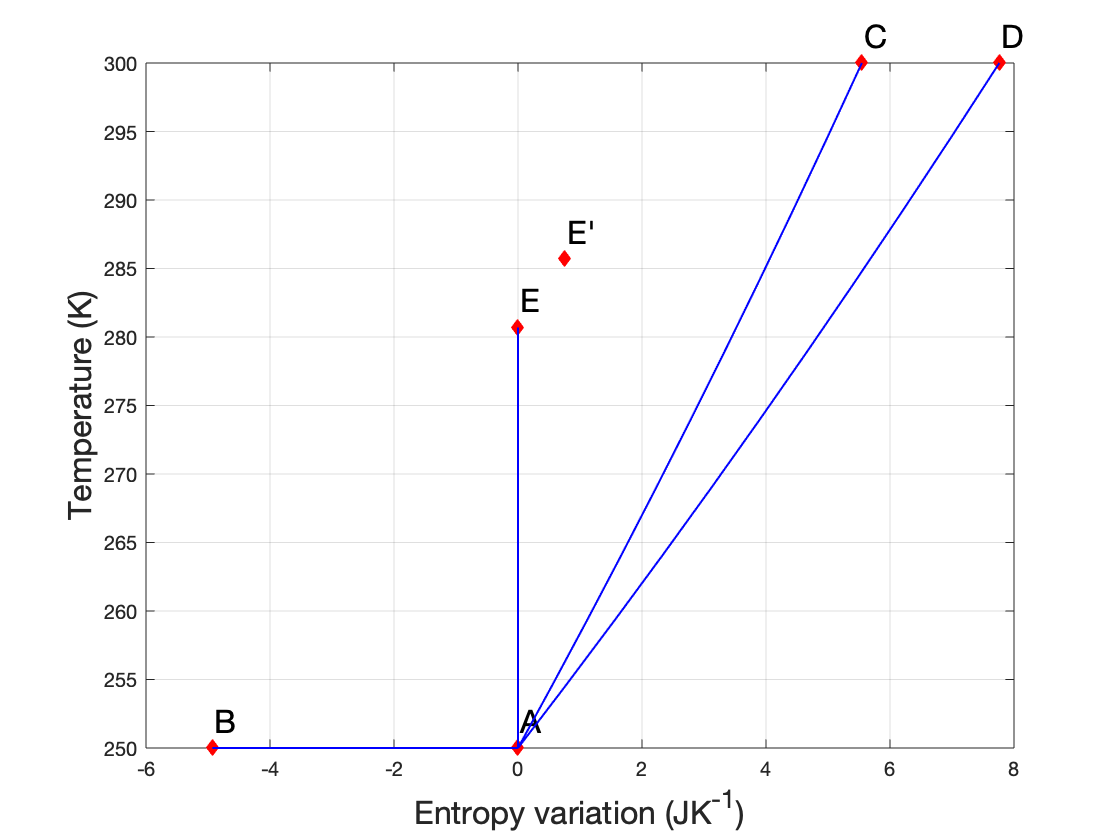


S=[0 DS_AB DS_AC DS_AD DS_AE DS_AEp];
plot(S,T,'dr','MarkerFaceColor','r')
xv=0.03; xp=2; % decalage écriture
text(0+xv,TA+xp,'A','FontSize',16,'color','k')
text(DS_AB+xv,TB+xp,'B','FontSize',16,'color','k')
text(DS_AC+xv,TC+xp,'C','FontSize',16,'color','k')
text(DS_AD+xv,TD+xp,'D','FontSize',16,'color','k')
text(DS_AE+xv,TE+xp,'E','FontSize',16,'color','k')
text(DS_AEp+xv,TEp+xp,'E''','FontSize',16,'color','k')
xlabel('Entropy variation (JK^{-1})','FontSize',16)
ylabel('Temperature (K)','FontSize',16)
grid on
hold on
Sx=[0 DS_AB]; Tx=[TA TB];
plot(Sx,Tx,'-b','lineWidth',1)   % isotherme
Sx=0:(DS_AC-0)/10:DS_AC;
Tx=TA*exp(Sx/n/Cv);
plot(Sx,Tx,'-b','lineWidth',1)  % isochore
Sx=0:(DS_AD-0)/10:DS_AD;
Tx=TA*exp(Sx/n/Cp);
plot(Sx,Tx,'-b','lineWidth',1) % isobare
Sx=[0 DS_AE]; Tx=[TA TE];
plot(Sx,Tx,'-b','lineWidth',1)   % adiabatic
hold off

## **Exo 4.5 :**** Veron’s cycle **

(follow-up questions of exercise III.7 : you’ll need the previous results)

- Calculate the entropy variations $\Delta S_1$, $\Delta S_2$, $\Delta S_3$ and $\Delta S_4$ of the gas, corresponding to the different processes (isothermal, isochoric, isobaric and adiabatic) 

- Check that entropy is a state function and plot the $(S-T)$ diagram representing the cycle

-  Make a graphical evaluation of the total heat on the cycle. 

**Recall of the numerical results calculated in Exo. 3-7**

n=10; Cv=20.8; R=8.314; Cp=R+Cv;g=Cp/Cv; PA=100; TA=300; atm=101325;
VA=n*R*TA/(PA*atm);  % in m^3
PB=10; VB=PA*VA/PB; TB=TA;
W1=n*R*TA*log(VB/VA); Q1=-W1; DU1=0; 
PC=2; TC=TB*PC/PB; VC=VB; W2=0;
DU2=n*Cv*(TC-TB); Q2=DU2;
PD=PC;VD=VA*(PA/PC)^(1/g); TD=TC*VD/VC;
W3=-PC*(VD-VC)*atm; Q3=n*Cp*(TD-TC); DU3=W3+Q3;
Q4=0; DU4=n*Cv*(TA-TD); W4=DU4;
Vi=[VA;VB;VC;VD]*1000;  % in L 
Pi=[PA;PB;PC;PD];       % in atm
Ti=[TA;TB;TC;TD];

**1) **Calculate the entropy variations $\Delta S_1$, $\Delta S_2$, $\Delta S_3$ and $\Delta S_4$ of the gas, corresponding to the different processes (isothermal, isochoric, isobaric and adiabatic) 

**AB** : isothermal, therefore $T=Cte=T_A$, ${dS}_1 =\frac{\delta Q_1 }{T_A }\iff {\Delta S}_1 =\frac{Q_1 }{T_A }=\frac{-W_1 }{T_A }=nR\ln\frac{V_B }{V_A }$   since $W_1=nRT_A\ln\frac{V_B}{V_A}$

**BC** : isochoric : ${dS}_2 =\frac{\delta Q_2 }{T}=\frac{n{\bar{\mathrm{C}} }_V dT}{T}\iff {\Delta S}_2 =n{\bar{C} }_V \mathrm{ln}\frac{T_C }{T_B }$ 

**CD **: isobaric : $dS_3 =\frac{\delta Q_3 }{T}=\frac{n{\bar{C} }_P dT}{T}\iff {\Delta S}_3 =n{\bar{C} }_P \mathrm{ln}\frac{T_D }{T_C }$

**DA** : reversible adiabatic : ${\Delta S}_4 =0$

DS1=n*R*log(VB/VA);DS2=n*Cv*log(TC/TB);DS3=n*Cp*log(TD/TC);DS4=0;
DSi=[DS1 DS2 DS3 DS4]

DSi =   191.4369 -334.7631  143.3262         0


**2) **Check that entropy is a state function and plot the (*T*, *S*) diagram representing the cycle

If we define the enropy varition $\Delta S$ of the system, such that $\Delta S =\sum_{i=1}^{4} \Delta S_i$ and make the numerical calculation, we see that it is nil over a cycle, showing that the entropy of the system is a state function

fprintf('sum DSi = %1.1f JK^-1',sum(DSi))

sum DSi = 0.0 JK^-1

There is a slight difference in that plot $T(S)$ as compared to for instance the Clapeyron's diagram $P(V)$, since we have only calculated entropy variations, for instance the variation between states A and B. We don't know the value of the entropy at a give state, which also means that we only know the value to a constant. Therefore we need to find a reference state point, for instance A for which we arbitrally fix the entropy to 0. As for the Clapeyron's diagram, we need to define the different curves :

**AB** : isothermal, so that the temperature is constant, therefore we have an horizontal line that starts in A, such that $S_A=0$ and since $\Delta S_{AB}=+191\,\mathrm{JK^{-1}}$, the point B will have the arbitrary value $S_B=191\,\mathrm{JK^{-1}}$.

**BC **: isochoric, neither $T$ nor $S$ are constant, so that one needs to establish the curve $T(S)$. For this, one can write the definition of the entopy between the point B and a given point X located between B and C, so that $dS_{BX}=\frac{\delta Q}{T}=\frac{n\bar C_vdT}{T}$ $\iff \Delta S_{BX}=n\bar C_v \ln\frac{T_x}{T_B}$ $\iff T_x=T_B\exp\frac{\Delta S_{BX}}{n\bar C_v}$, this represents the curve of the funtion $T_x=f(\Delta S_{BX})$.

**CD** : isobaric, again neither $T$ nor $S$ are constant, so that one needs to establish the curve $T(S)$, Considering the same methodology for a given point X between C and D, one can write : $dS_{CX}=\frac{\delta Q}{T}=\frac{n\bar C_pdT}{T}$ $\iff \Delta S_{CX}=n\bar C_p \ln\frac{T_x}{T_C}$ $\iff T_x=T_C\exp\frac{\Delta S_{CX}}{n\bar C_p}$

**DA **: Over the adiabatic process the entropy variation $\Delta S_{DA}=0$, therefore the curve is a vertical straigth line.

Both curves BC and CD are described by similar functions, where the difference, is $\bar C_p$ or $\bar C_v$ on the denominator, their shape are therefore close, and when trying to plot both curbes at the same point C, one may find out the relative values of the derivates, that are : ${\Big(\frac{dT}{dS}\Big)}_V=\frac{T}{n\bar C_v}$ and ${\Big(\frac{dT}{dS}\Big)}_P=\frac{T}{n\bar C_p}$. Since $\bar C_p>\bar C_v$, then the slope of isochoric curve is larger.

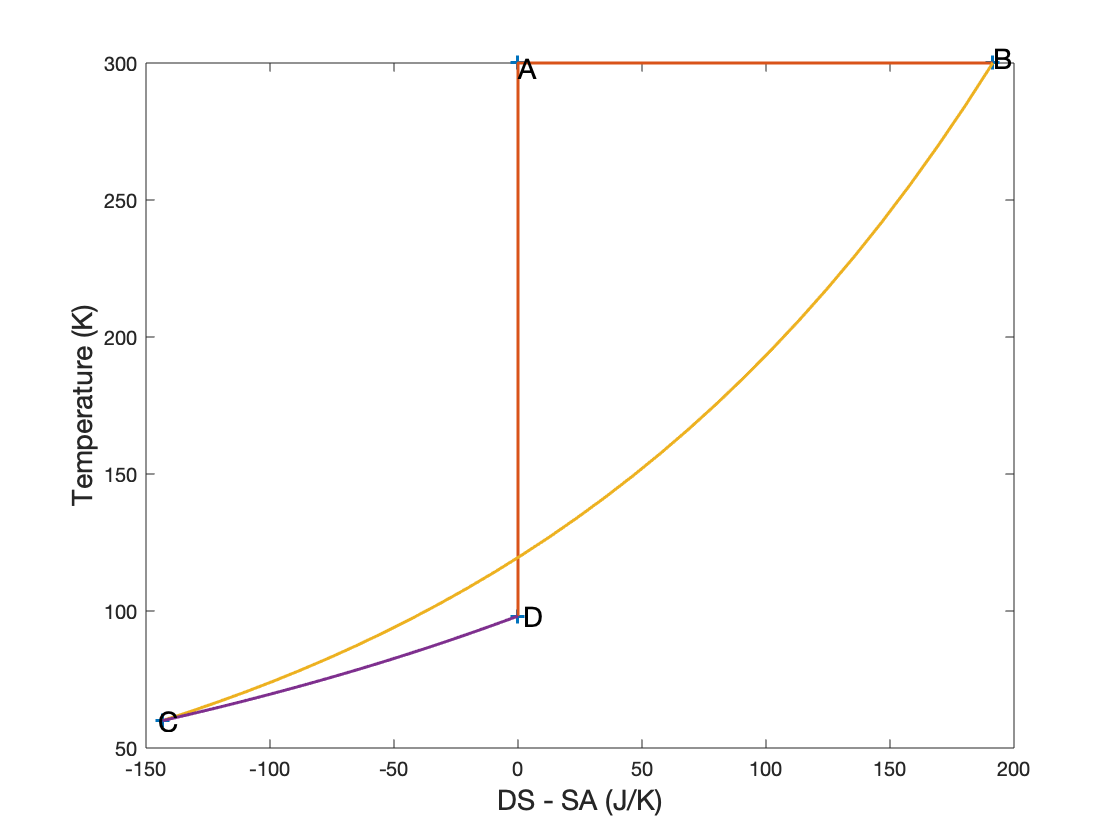

Si=[0 DS1 DS1+DS2 DS1+DS2+DS3];
figure
plot(Si,Ti,'linewidth',1.5,'LineStyle','none','Marker','+') % plot of the diff states
T1=[Ti(4) Ti(1) Ti(2)]; % tracé adiabatic et isotherme
S1=[Si(4) Si(1) Si(2)];
hold on
plot(S1,T1,'linewidth',1.5,'LineStyle','-','Marker','none')
S2=Si(2):(Si(3)-Si(2))/30:Si(3);
T2=Ti(2).*exp((S2-Si(2))./(n*Cv));
plot(S2,T2,'linewidth',1.5,'LineStyle','-','Marker','none')
S3=Si(3):(Si(4)-Si(3))/30:Si(4);
T3=Ti(3).*exp((S3-Si(3))./(n*Cp));
plot(S3,T3,'linewidth',1.5,'LineStyle','-','Marker','none')
xlabel('DS - SA (J/K)','FontSize',14)
ylabel('Temperature (K)','FontSize',14)
text(Si(1),Ti(1)-2,'A','FontSize',14)
text(Si(2),Ti(2)+2,'B','FontSize',14)
text(Si(3)-2,Ti(3),'C','FontSize',14)
text(Si(4)+2,Ti(4),'D','FontSize',14)
hold off

DS=sum(DSi); fprintf('DS = %2.1f J/K',DS)

DS = 0.0 J/K

## **Exo 4.6 : Sealed glass**

A sealed glass containing $m=10\,\mathrm{g}$ of water (liquid + saturation vapour) is deposited in a vessel of constant volume $V$ linked to a thermostat at temperature $T_1=373\,\mathrm{K}$ . In the initial state the vessel is empty and the water (negligible volume compared to $V$) at temperature $T_1$ and pressure $P_1$  equal to the saturation vapour pressure at temperature  $T_1$, 1bar. The glass is opened in the vessel. 

**1) a) **Calculate the particular value $V_c$  of the volume $V$ such that in the final equilibrium state, water is only present in the vapour state, at saturation pressure $P_1$ and temperature  $T_1$.

    Initial state : 10 g of liquid water + negligeable quantity of vapour.

    final state : only vapour.

    Hypothesis : As soon as we open the sealed glass, the few vapour molecules initially present occupy the full volume, therefore with a nil pressure. 

We apply the first law with the pressure equals the saturating vapour pressure :

    
$$V_c=\frac{mRT_1}{M_{H_2O}P_{VS}}$$


M_H2O=18e-3; m=10e-3; T1=373; Pvs=1e5;
Vc=m*R*T1/(M_H2O*Pvs); fprintf('Vc = %1.1f L',Vc*1e3) % in m^3

Vc = 17.2 L

**b)** For the above process, calculate the heat received by water $Q$, the entropy variation received by water and the entropy exchanged. Conclude.

    We assume a **constant volume process**, since we have immediatly somme vapour in all the volume.

    
$$Q=Q_v=\Delta U=\Delta H-\Delta(PV)=\Delta H-V_c\Delta(P)$$
 
$$\iff Q=m\Delta_{vap}\bar H-V_c(P_{vs}-0)$$


    $\Delta S_\sigma=\frac{m\Delta_{vap}\bar H}{T_1}$  and  $S_e=\frac{Q}{T_1}$  then  $S_c=\Delta S_\sigma - S_e$

DvapH_w=2300e3; 
Q=m*DvapH_w-Vc*Pvs; fprintf('Q = %1.1f kJ',Q/1e3) % in J

Q = 21.3 kJ

DS_s=m*DvapH_w/T1; fprintf('DS_s = %1.1f J/K',DS_s)   % in J/K

DS_s = 61.7 J/K

S_e=Q/T1; fprintf('S_e = %1.1f J/K',S_e)     % in J/K

S_e = 57.0 J/K

S_c=DS_s-S_e; fprintf('S_c = %1.1f J/K',S_c)  % in J/K

S_c = 4.6 J/K

**2)** We suppose $V$ to be lower than $V_c$. Express the vapour molar fraction in the final equilibrium state as function of $V$ and $V_c$ .

    The final pressure is $P_{vs}$  $m_v=M_{H_2O}\frac{P_{vs}V}{RT_1}$ so that the molar fraction is $\chi_v=\frac{m_v}{m}=\frac{V}{V_c}$

**3)** We suppose $V$ to be higher than $V_c$ . Express the pressure in the final equilibrium state as function of  $P_1$,$V$ and  $V_c$.

    all vaporised so that $P_f=\frac{nRT_1}{V}$ $\iff \frac{P_f}{n}=\frac{RT_1}{V}=\frac{P_{vs}}{n_v}$ $\iff P_f=P_{vs}\frac{n}{n_v}=P_{vs}\frac{V_c}{V}$

## **Exo 4.7 : Student and sport**

A first year INSA student prone of thermodynamics wishes to cut off his budget. Since he likes doing sport, he decides to develop a system to heat up his room while doing some sport. His idea is to convert the compression work of a gas to heat. Both parts of this exercise are independent, but information given in the text in I-A can be useful for the I-B.  Given $P_0  = 1\,\mathrm{atm}$  $\bar C_v=\frac{R}{\gamma-1}$, $\bar C_p=\frac{R\gamma}{\gamma-1}$, taking  $\gamma= 1.4$ for air.

**I-A Model of the problem :**

We consider a system of $n_0$ moles of air entrapped in a cylinder closed by a mobile piston. The system is disposed in a room and in the initial state (I), is at equilibrium with the air of the room which temperature and pressure are assumed constant and equal to $T_0$ and $P_0$ respectively. We write $V_0$ the volume of the system in the initial state. The idea is to compress the air contained in the cylinder until a state F and to release the piston so that the air is back to the initial state, therefore describing the following cycle :

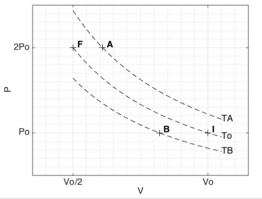

**Process 1** from I $(T_0, P_0, V_0$) to A $(T_A, P_A = 2P_0, V_A)$ : the air in the cylinder is first abruptly compressed by the student under a pressure of $2P_0$. 

**Process 2** from A to F $(P_F = 2P_0, T_F  = T_0, V_F = V_0/2)$ : while maintaining a pressure at $2P_0$, the student waits until equilibrium is reached between the air in the cylinder and that of the room (assumed a thermostat at temperature $T_0$).

**Process 3** from F to B  $(T_B, P_B = P_0, V_B)$ : the student abruptly releases the piston. 

**Process 4** from B to I : the student waits until equilibrium is again reached.  

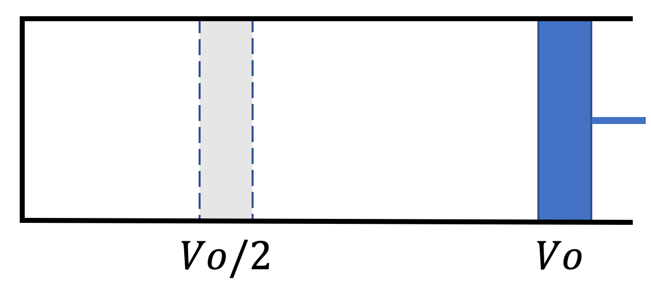

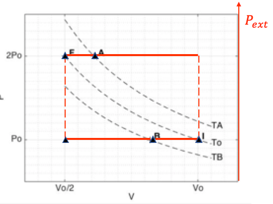

**1)** Explain why the processes 1 and 3 can be assumed adiabatic and processes 2 and 4 are monobaric. 

    1 and 3 are fast so that no time for heat exchange, which a rather slow process so that they are adiabatic. 

**2)  a) **Give the expressions of the works transferred during the four processes $W_1, W_2, W_3$ and $W_4$ as a function of $P_0, V_0, V_A$ and $V_B$. 

    IA :  Constant external pressure : $\delta W_1=-P_{ext}dV$  with $P_{ext}=2P_0$  then $W_1=-2P_0(V_A-V_0)$ ; 

    AF : pressure constant, similar : $W_2=-2P_0\bigg(\frac{V_0}{2}-V_A\bigg)$; 

    FB : constant external pressure  $P_{ext}=P_0$  $\iff W_3=-P_0\bigg(V_B-\frac{V_0}{2}\bigg)$; 

    BI : The external pressure is still constant : $W_4=-P_0(V_0-V_B)$

  **b)** Give the expressions of the heat transferred during the four processes $Q_1, Q_2, Q_3$ and $Q_4$ as a function of quantities to select within $T_0, T_A, T_B, \bar C_v  , \bar C_p , n_0, R$.

    Adiablatic processes so that : $Q_1=0$ and $Q_3=0$ ; 

    Isobarric processes so that $Q_2=n_0\bar C_p(T_0-T_A)$ and  $Q_4=n_0\bar C_P(T_0-T_B)$

**3)** Show that the heat received by the room during the cycle is equal to $P_0V_0/2$.

   The full process is a cycle so that $\Delta U=0\iff Q=-W\iff Q=Q_2+Q_4=-(W_1+W_2+W_3+W_4)$

    
$$\iff Q=P_0(-2V_A+2V_0-V_0+2V_A-V_B+V_B/2-V_0+V_B)=\frac{P_0V_0}{2}$$


**4)** Writing by two different ways the work transferred during the compression (1 + 2), i.e. from I to F, show that $T_A=T_0\frac{2\gamma-1}{\gamma}$ . Similarly (thanks to the work of the expansion (3 + 4) show that $T_B=T_0\frac{\gamma+1}{2\gamma}$.

    Between I to F, temperature constant and for an ideal gas $T=cte \rightarrow  \Delta U =0$

    
$$\Delta U_{1+2}=0=W_1+W_2+Q_2$$
 
$$\iff -2P_0\Big( \frac{V_0}{2}-V_0\Big)=-n_0\bar C_p(T_0-T_A)$$
 

                                                
$$\iff P_0V_0=-n_0\bar C_p(T_0-T_A)$$


                                                 
$$ \iff RT_0=-\bar C_p(T_0-T_A)$$


                                                 
$$ \iff T_A= T_0\frac{R+\bar C_p}{\bar C_p}+1=T_0\frac{2\gamma+1}{\gamma}$$
  


$$\Delta U_{3+4}=0=W_3+W_4+Q_4$$
 
$$\iff -P_0\Big( V_0-\frac{V_0}{2}\Big)=-n_0\bar C_p(T_0-T_B)$$
         

                                        
$$\iff -\frac{P_0V_0}{2}=-n_0\bar C_p(T_0-T_B)$$
 

                                        
$$ \iff -\frac{RT_0}{2}=-\bar C_p(T_0-T_B)$$
 

                                        $ \iff T_B= T_0\big(1-\frac{R}{2\bar C_p}\big)=T_0\frac{\gamma+1}{2\gamma}$   since $\frac{R}{\bar C_p}=\frac{\gamma-1}{\gamma}$

**5)** Express the entropy variation of the system, then of the room during the cycle. 

This is a cycle, then $\Delta S_\sigma=0$ , $S_e=\frac{Q_2}{T_0}+\frac{Q_4}{T_0}$ $\iff S_e=n_0\bar C_p\bigg(\frac{(T_0-T_A)}{T_0}+\frac{(T_0-T_B)}{T_0}\bigg)$

**6)** Check that this cycle is indeed possible but irreversible.

$S_c=\Delta S_\sigma-S_e>0$ since  $\iff -S_e=n_0\bar C_p\bigg(\frac{T_A}{T_0}-1+\frac{T_B}{T_0}-1\bigg)$

**I-B Possibility of this project, orders of magnitude : **

The volume of air in the room is $V = 25\,\mathrm{m^3}$ and the pressure is constant, equal to $P_0$. The room being fairly well insulated, when the student is back in the evening the temperature is equal to $T_{min} = 17\mathrm{°C}$. However, in order to work correctly, the student wishes a temperature equal to $T_{max} = 21\mathrm{°C}$. He makes a cylinder of length $L = 2.0\,\mathrm{m}$ and cross section $S = 10\,\mathrm{cm^2}$. 

**7)** Calculate the number of moles of air $n_{room}$ contained in the room. 

    
$$n_{room}=\frac{P_0V}{RT_{min}}$$


P0=101325; V=25; Tmin=273+17; Tmax=273+21; L=2; S=10e-4;
n_room=P0*V/R/Tmin; ; fprintf('n_room = %1.0f mol',n_room) % in mol

n_room = 1051 mol

**8)** Calculate the heat quantity $Q_{total}$ required to increase the temperature of the room from $T_{min}$ to $T_{max}$.

    
$$Q_{total}=n_{room}\bar C_p(T_{max}-T_{min})$$


Q_tot=n_room*Cp*(Tmax-Tmin); fprintf('Q_tot = %1.0f kJ',Q_tot/1e3) % in J

Q_tot = 122 kJ

**9)** Assuming the compression is done under a pressure $2P_0$ (as in part A), what force must the student apply on the cross section of the cylinder in addition to the atmospheric pressure force? Do you think the value reasonable? (Justify).  

    
$$F=(2P_0-P_0)S$$


F=(2*P0-P0)*S; fprintf('F = %1.0f N',F) % in N

F = 101 N

The force to apply is $F=101\,\mathrm{N}$

equivalent to 10 kg so that not too high.

**10)** How many cycles must the student operate to heat up his room? Do you find the result reasonable? 

    For one cycle the work is $W_{cycle}=\frac{P_0V_0}{2}=\frac{P_0LS}{2}$

    
$$N_{cycle}=\frac{Q_{total}}{W_{cycle}}$$


W_cycl=P0*L*S/2; N_cycl=Q_tot/W_cycl; fprintf('N_cycl = %1.0f cycles',N_cycl)

N_cycl = 1208 cycles

## **Exo 4.8 Use of a heat pump to heat up a swiming pool. **

A recreation center, closed to a lake wishes to build up a swiming pool that could be heated up by a heat pump. We have the following specifications :

- The swiming pool contains $200\,\mathrm{m^3}$ of water, corresponding to a weight $m$

- The water is taken directly from the lake

- The mean temperature of the lake water is $T_L=283\,\mathrm{K}$.

- The mean temperature of the swiming pool is set to $T_S=303\,\mathrm{K}$

- A daily heat quantity of $Q_S=1.6\,\mathrm{MJ}$ is used to maintain the temperature of the swimming pool constant.

**A. Maintaining the temperature constant**

**1. **A daily heat quantity of $Q_S=1.6\,\mathrm{MJ}$ is used to maintain the temperature of the swimming pool constant.  Applying the first and the second thermodynamics  laws give a literal expression as function of $Q_S ,T_L$ and $T_s$ of the mechanical work required to maintain the temperature of the swiming pool constant. Calculate the consumed electric energy. For this purpose, we assume that 

- the heat pump exhibits a reversible cyclic working,

- the heat supplied by the engine is entirely transferred to water,

- the efficiency of the electric engine of the heat pump is equal to $\eta=95\%$,

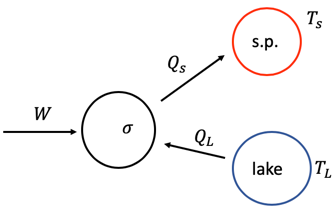

We consider the gas of the pump as the system $\sigma$

    first law : $\Delta U=W+Q_L+Q_S=0$ (1) ,  since over a cycle

    second law : $\Delta S_\sigma=S_c+S_e^L+S_e^s$$\iff S_c=\Delta S_\sigma-S_e^L-S_e^s\iff-\frac{Q_L}{T_L}-\frac{Q_S}{T_S}=0$  (2)  since reversible $S_c=0$, and over a cycle $\Delta S_\sigma=0$

    Combining (1) and (2)  leads to $W=-Q_S\bigg(1-\frac{T_L}{T_S}\bigg)$

    Therefore $W_e=\frac{W}{\eta}$

T_L=283; T_S=303; c_w=4.18e3; m=200e3; eta=0.95; Q_S=-1.6e6; eta=0.95;
W=-Q_S*(1-T_L/T_S); fprintf('W = %1.0f kJ',W/1e3)

W = 106 kJ

We=W/eta; fprintf('We = %1.0f kJ',We/1e3)

We = 111 kJ

**2. **What would have been the electrical energy supplied if the  temperature of swiming pool was kept constant using an elecrical resistance, assuming that this energy is fully transferred to water. Comment.

In that case we need to spend the full quantity $Q_s$ in elecric energy, so that : $W_e=\frac{Q_s}{\eta}$

We=-Q_S/eta; fprintf('We = %1.0f kJ',We/1e3)

We = 1684 kJ

**B. Heating the temperature of the swimming pool**

We now consider that the initial temperature of the swimming pool is $T_L$ and that the heat pump is used to heat up the water of the pool from $T_L$   to $T_S$ . Applying the first and the second thermodynamics laws give a literal expression as function of $m,c_w,T_L$  and $T_S$ of the mechanical work required to heat up the swimming pool from $T_L$  to $T_S$ . Calculate the consumed electric energy.

Owing to this variation, let's write the differential form the first and second laws

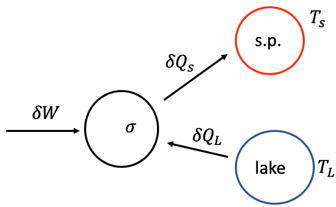

We know that $\delta W>0$, $\delta Q_s<0$, $\delta Q_L>0$

**First law **of a cyclic system leads to : 

    $dU=\delta W+\delta Q=0$ $\iff\delta W + \delta Q_L+\delta Q_S=0$     $\delta Q_s=-mc_wdT$ (since $<0$ for temperature increase

    $\iff \delta W+\delta Q_L-mc_wdT=0$ (1)

**Second law **gives :  

    $\delta S_c=dS_\sigma-\delta S_e^L-\delta S_e^s=0$, since reversible and since it operates over a cycle : $dS\sigma=0$

     $ \delta S_e^s+\delta S_e^L=0$ $\iff \frac{\delta Q_L}{T_L}+\frac{\delta Q_S}{T}=0$ $\iff \frac{\delta Q_L}{T_L}+\frac{-mc_wdT}{T}=0$ (2)

the eqn (2) becomes : $\delta Q_L=T_L\frac{mc_wdT}{T}$, substituting in eqn (1) gives : $\delta W+T_L\frac{mc_wdT}{T}-mc_wdT=0$ $\iff$ $\delta W=-T_L\frac{mc_wdT}{T}+mc_wdT$

Integrating leads to $W=\int_{T_L}^{T_S}\delta W$ $\iff W=mc_w\big(-T_L\ln\frac{T_S}{T_L}+(T_S-T_L)\big)$

The electric work is $W_e=\frac{W}{\eta}$

W=m*c_w*(-T_L*log(T_S/T_L)+(T_S-T_L)); fprintf('W = %1.2f MJ',W/1e6)

W = 564.37 MJ

We=W/eta; fprintf('We = %1.2f MJ',We/1e6)

We = 594.08 MJ

the electrical work is $W_e=594\,\mathrm{MJ}$

## **Exo 4.9 : Diesel engine** 

The working of a diesel can be described by a theoretical thermodynamic cycle which gives in a Clapeyron’s diagram :

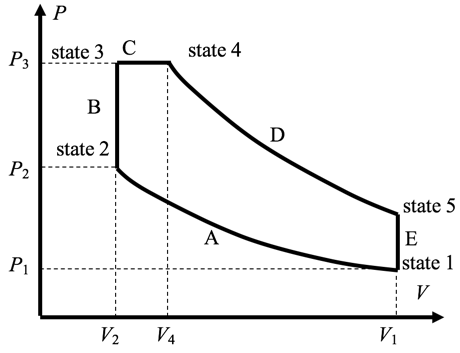

In the initial state (State 1), we consider one mole of ideal gas occupying a volume $V_1$ at the temperature $T_1$, under the pressure $P_1$, which is submitted to the following reversible processes:

- A. Adiabatic compression to volume $V_2$ such that $V_1/V_2=a$.

- B. Increase of the pressure, by a supply of heat at constant volume until the pressure $P_3$ such that $P_3P_2=b$. 

- C. Expansion by supply of heat at constant pressure, until the volume $V_4$ such that $V_4/V_3=c$.

- D. Adiabatic expansion until the volume $V_5=V_1$

- E. Cooling at constant volume until the pressure $P_1$.

1) Express as function of $T_1,a,b,c$ and $\gamma$, the temperatures $T_2,T_3$ and $T_4$, supposing the thermal capacities $\bar C_P$ and $\bar C_V$ temperature independent. Show that $T_5=bc^\gamma T_1$.

    A: adiabatic : $P_1{V_1}^\gamma=P_2{V_2}^\gamma$ $\iff P_2=P_1\Big(\frac{V_1}{V_2}\Big)^\gamma=P_1a^\gamma$  and $T_1{V_1}^{\gamma-1}=T_2{V_2}^{\gamma-1}$$\iff T_2=T_1\Big(\frac{V_1}{V_2}\Big)^{\gamma-1}=T_1a^{\gamma-1}$

    B : $V=Cte$ $\frac{P_2}{T_2}=\frac{P_3}{T_3}$ $\iff T_3=T_2\frac{P_2}{P_3}=bT_2=bT_1a^{\gamma-1}$

    C: $P=Cte$ $\frac{V_3}{T_3}=\frac{V_4}{T_4}$ $\iff T_4=T_3\frac{V_4}{V_3}=cT_3$ $\iff T_4=T_1a^{\gamma-1}bc$

    D: Adiabatic  $T_4{V_4}^{\gamma-1}=T_5{V_1}^{\gamma-1}$ $\iff T_5=T_4\Big(\frac{V_4}{V_1}\Big)^{\gamma-1}=T_1a^{\gamma-1}bc\Big(\frac{V_4}{V_1}\Big)^{\gamma-1$

    E: in addition, $V_4=cV_3$ and $V_3=V_2$ $\rightarrow V_4=cV_2$      $V_2=V_1/a$       $V_4=\frac{a}{c}V_1$

    in the end : $T_5=T_1a^{\gamma-1}bc\Big({\frac{c}{a}\Big)^{\gamma-1}=T_1bc^\gamma$

2) Express as function of $\bar C_V, \gamma$ and of the ratios $T_3/T_2, T_4/T_3$ and $T_1/T_5$ the total entropy variation of one mole of gas submitted to this cycle. Check from the result of part 1) that entropy is a state function.

    $\Delta S_A=\Delta S_D=0$ ; $\Delta S_B=\bar C_V\ln \frac{T_3}{T_2}$ and $\Delta S_C=\bar C_P\ln \frac{T_4}{T_3}=\gamma\bar C_V\ln \frac{T_4}{T_3}$,  $\Delta S_E=\bar C_V\ln \frac{T_1}{T_5}$ 

    since  $\Delta S_{cycle}=\Delta S_B+\Delta S_C+\Delta S_E=\bar C_V\ln\frac{T_3}{T_2}\Big(\frac{T_4}{T_3}\Big)^\gamma\frac{T_1}{T_5}$ $=\bar C_V\ln\Big( b c^\gamma\frac{1}{bc^\gamma}\Big)=0$

3) $Q_1$ is the total heat quantity exchanged between the air and the surroundings during the processes B and C, $Q_2$ is the heat exchanged during the process E and $W$ the total work exchanged during the full cycle.

- a) What are for the mole of air, considered the reference the signs of $Q_1, Q_2$ and $W$ ?

- b) What is the relation between $Q_1, Q_2$ and $W$ ? Justify.

- c) Express $Q_1$ and $Q_2$ as function of  and $\bar C_V, T_1,a,b,c$ and $\gamma$.

   a)  increase of temp, so $Q_1>0$, $Q_2<0$ and $W<0$

   b) $Q_1+Q_2$ represents the total heat transfer, so that $\Delta U=Q_1+Q_2+W=0$

   c) $Q_1=\bar C_V(T_3-T_2)+\gamma \bar C_V(T_4-T_3)$ $\iff Q_1=\bar C_V(bT_1a^{\gamma-1}-T_1a^{\gamma-1}+\gamma T_1a^{\gamma-1}bc-\gamma bT_1a^{\gamma-1})$

        
$$Q_2=\bar C_V(T_1-T_5)=\bar C_V(T_1-T_1bc^\gamma)$$


4) Show that $Cop=1-\frac{bc^\gamma -1}{a^{(\gamma-1)}\big(b-1+\gamma b(c-1)\big)}$.

    
$$Cop=\frac{-W}{Q_1}=\frac{Q_1+Q_2}{Q_1}$$


    
$$Q_1=\bar C_VT_1a^{\gamma-1}(b-1+\gamma b(c-1))$$


    
$$Q_2=\bar C_VT_1(1-bc^\gamma)$$


    
$$Cop=\frac{\bar C_VT_1a^{\gamma-1}(b-1+\gamma b(c-1))+\bar C_VT_1(1-bc^\gamma)}{\bar C_VT_1a^{\gamma-1}(b-1+\gamma b(c-1))}$$
 
$$=\frac{a^{\gamma-1}(b-1+\gamma b(c-1))+(1-bc^\gamma)}{a^{\gamma-1}(b-1+\gamma b(c-1))}$$
 
$$=1-\frac{-(1-bc^\gamma)}{a^{\gamma-1}(b-1+\gamma b(c-1))}$$
